a_in = rtcpjd(31.25, 0, 0); % new incoming event every 31.25 ms
b1_in = rtcfs(22); % 22 000 resources (instructions) per time unit interval (millisecond)
b2_in = rtctdma(10,10,72); % bandwidth of 72 bpms, 8/10 slots of the bus -> CHANGE ME
b3_in = rtcfs(11);

% computation and communication demands e
e1 = 100; % # instructions needed
e2 = 32; % 32 bits need to be transfered using the bus
e3 = 100;
e4 = 32;
e5 = 500;

% deadlines d for all computation and communication tasks ??!

[a_out1, b1_out1, del1, buf1] = rtcgpc(a_in, b1_in, e1);
[a_out2, b2_out1, del2, buf2] = rtcgpc(a_out1, b2_in, e2);
[a_out3, b3_out, del3, buf3] = rtcgpc(a_out2, b3_in, e3);
[a_out4, b2_out2, del4, buf4] = rtcgpc(a_out3, b2_out1, e4);
[a_out5, b1_out2, del5, buf5] = rtcgpc(a_out4, b1_out1, e5);

% resulting curves
disp(['a_{in}']);

a_{in}


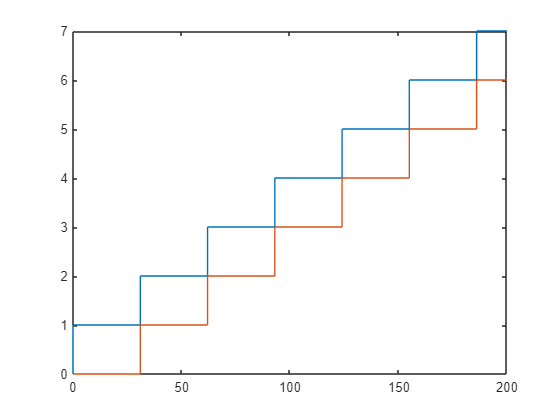

rtcplot(a_in, 200);

disp(['a_{out}']);

a_{out}


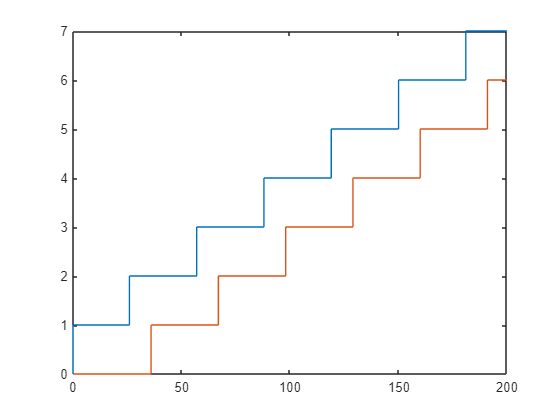

rtcplot(a_out5, 200);


disp(['b1_{in}']);

b1_{in}


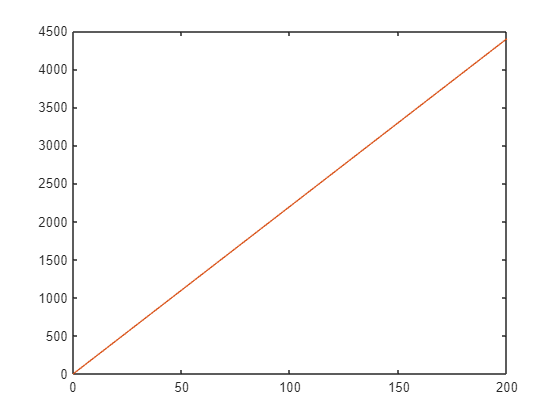

rtcplot(b1_in, 200);

disp(['b1_{out}']);

b1_{out}


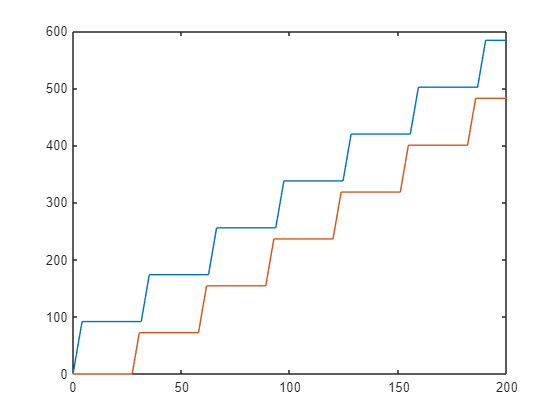

rtcplot(b1_out2, 200);


disp(['b2_{in}']);

b2_{in}


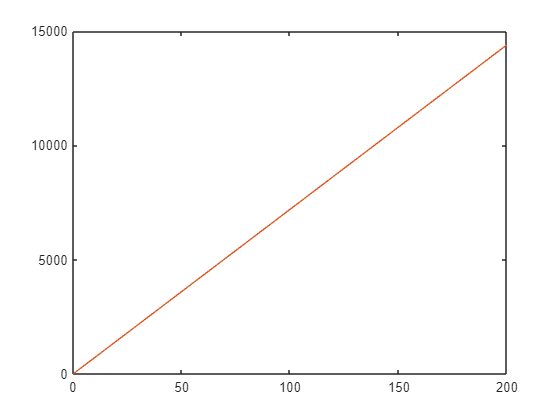

rtcplot(b2_in, 200);

disp(['b2_{out}']);

b2_{out}


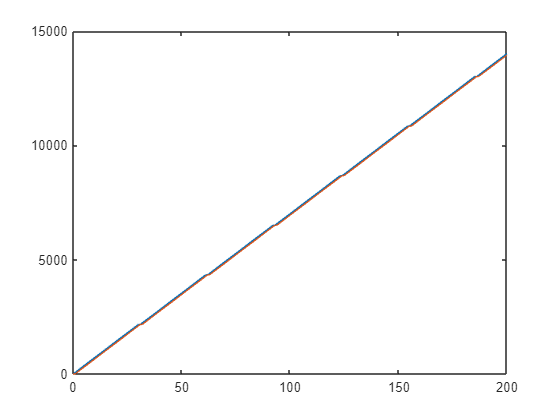

rtcplot(b2_out2, 200);


disp(['b3_{in}']);

b3_{in}


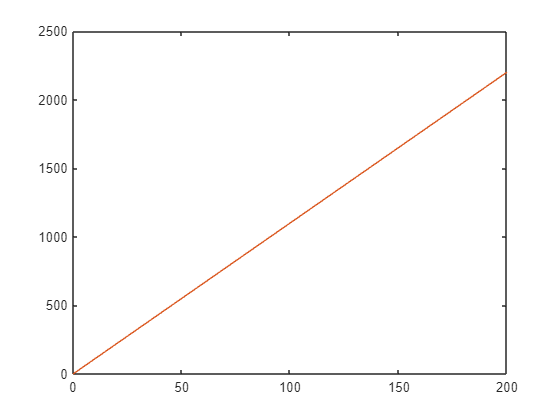

rtcplot(b3_in, 200);

disp(['b3_{out}']);

b3_{out}


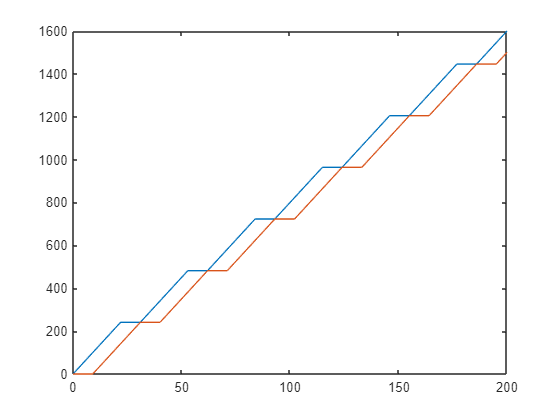

rtcplot(b3_out, 200);


delayL = del1 + del2 + del3 + del4 + del5;
delayT = rtcdel(a_in, b1_in, e1, b2_in, e2, b3_in, e3, b2_out1, e4, b1_out1, e5);
disp(['delay loosely = ', num2str(delayL), '; delay tighter = ', num2str(delayT)]);

delay loosely = 42.2424; delay tighter = 42.2424


disp(['del = ', num2str(del1)]);

del = 4.5455


disp(['del = ', num2str(del2)]);

del = 0.44444


disp(['del = ', num2str(del3)]);

del = 9.0909


disp(['del = ', num2str(del4)]);

del = 0.88889


disp(['del = ', num2str(del5)]);

del = 27.2727



bufferL = buf1 + buf2 + buf3 + buf4 + buf5;
bufferT = rtcbuf(a_in, b1_in, e1, b2_in, e2, b3_in, e3, b2_out1, e4, b1_out1, e5);
disp(['buffer loosely = ', num2str(bufferL), '; buffer tighter = ', num2str(bufferT)]);

buffer loosely = 5; buffer tighter = 2
